# 06 Homework: Isoparametric Finite Elements

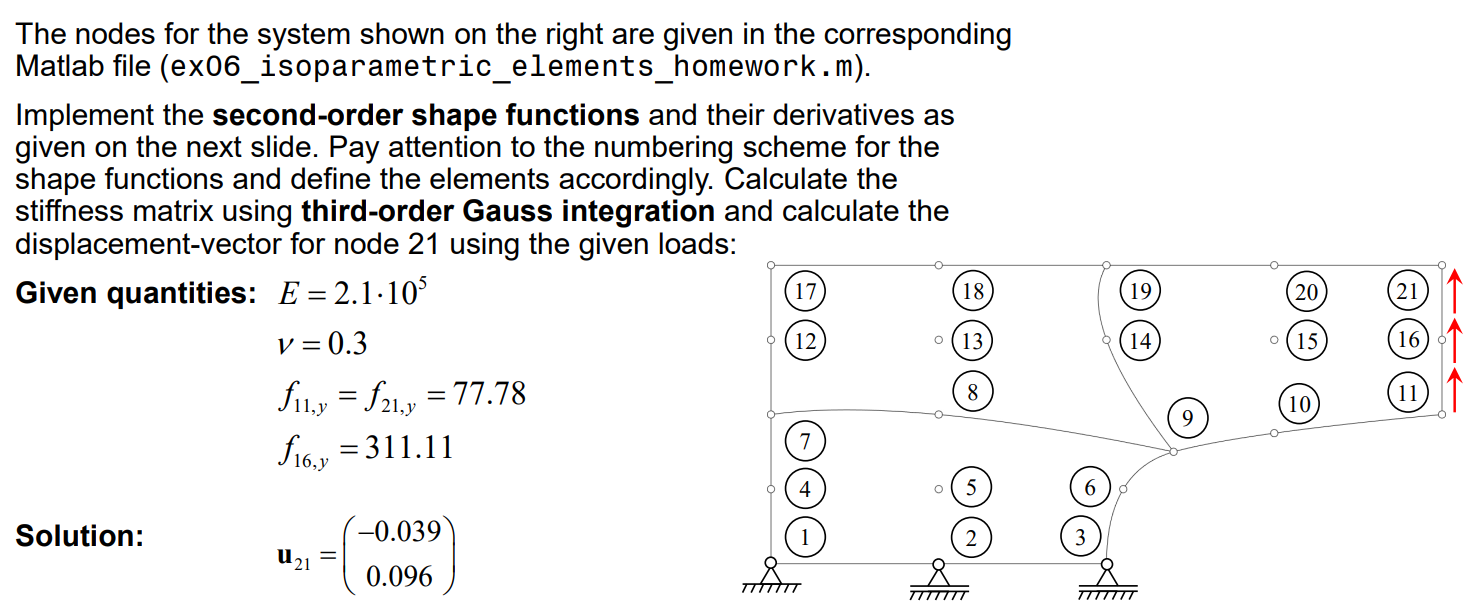

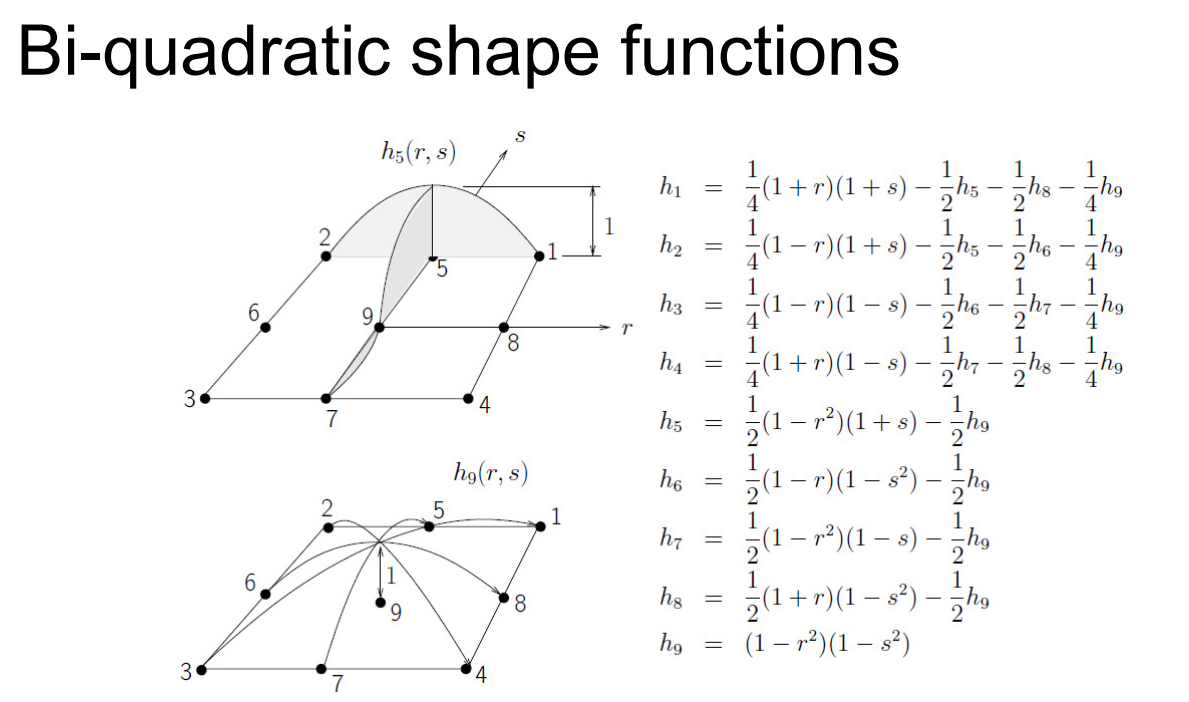

clear all; close all;

## Given parameters

E = 2.1e5;
nu = 0.3;

C = E / (1 - nu^2) * [1, nu, 0;
                      nu, 1, 0;
                      0,  0, (1 - nu) / 2];

## Model definition

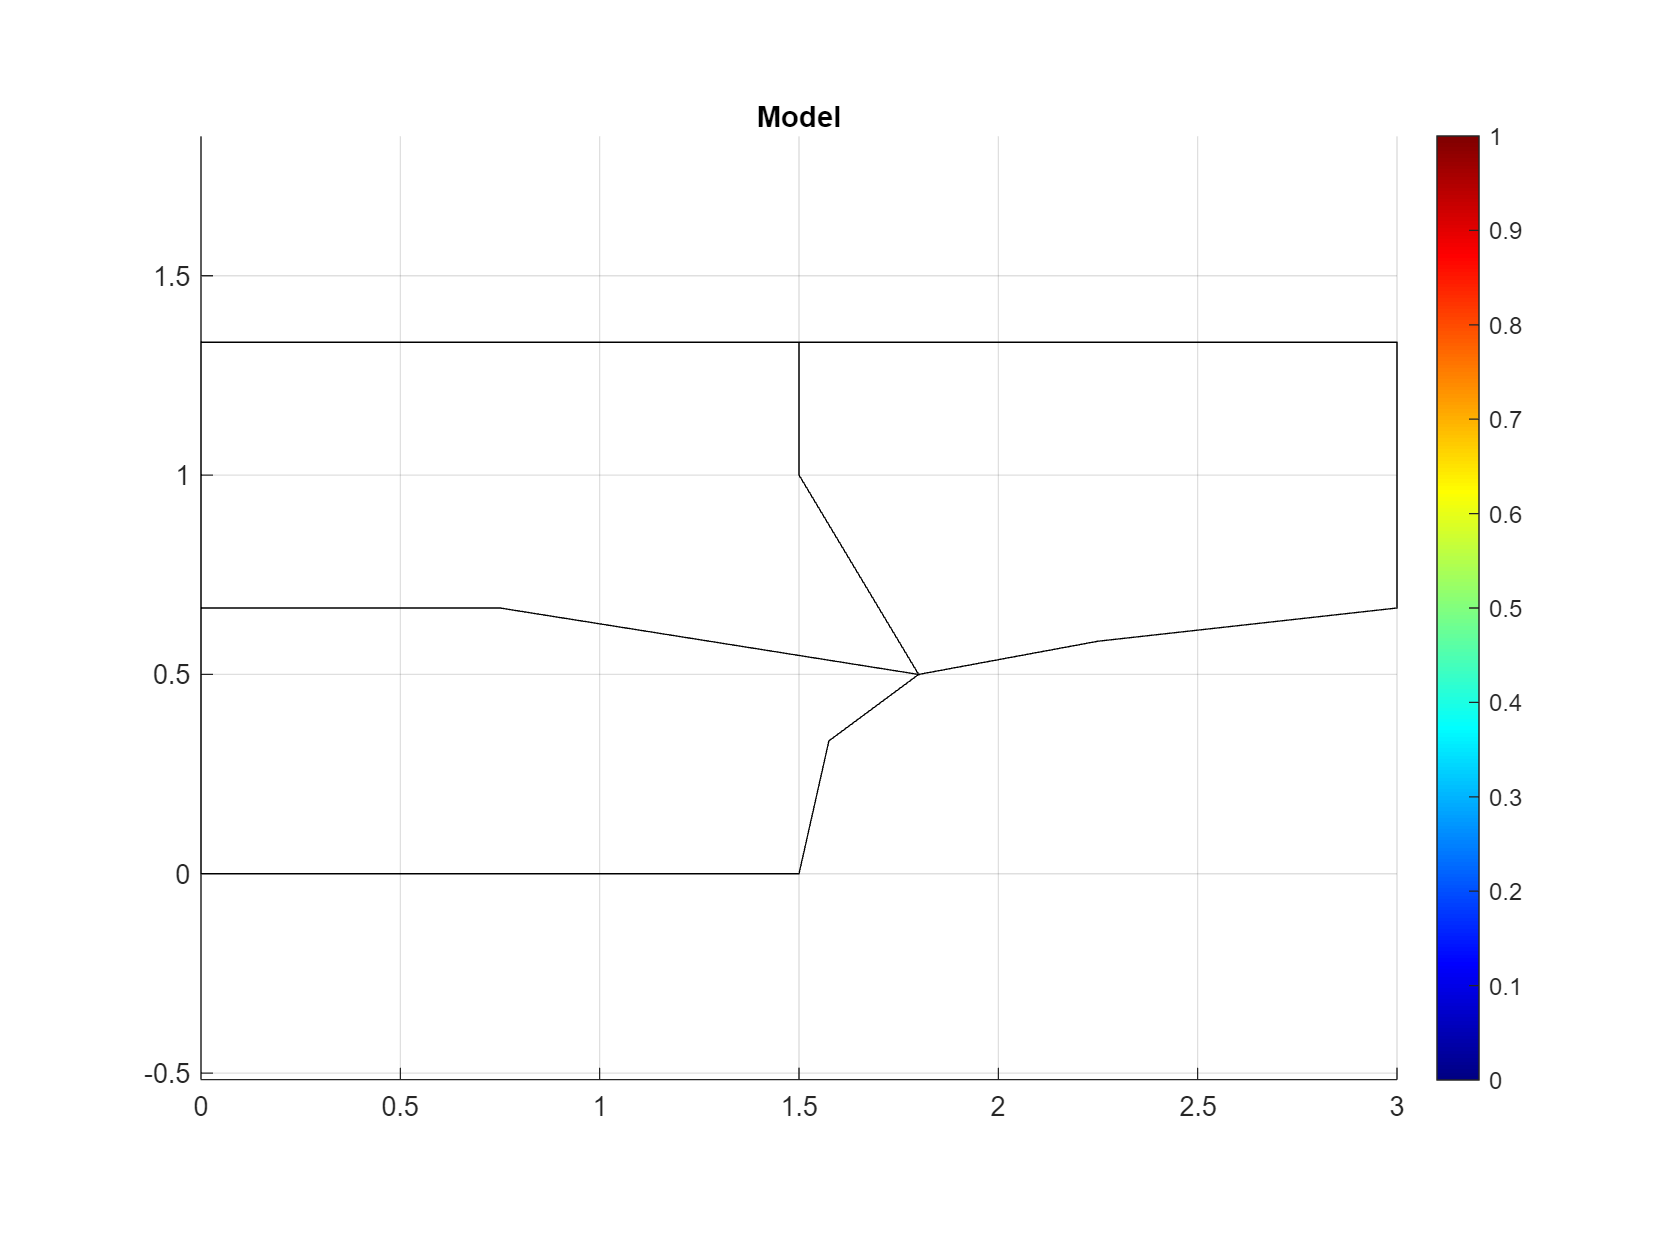

Lx = 1.5;
Ly = 2/3;
nodes = [0,0; Lx/2,0; Lx,0;
         0,Ly/2; Lx/2,Ly/2; Lx*1.05,Ly/2; 
         0,Ly; Lx/2,Ly; Lx*1.2,Ly*3/4;   1.5*Lx,Ly*7/8;  2*Lx,Ly; 
         0,1.5*Ly; Lx/2,1.5*Ly; Lx,1.5*Ly; Lx*1.5,1.5*Ly; 2*Lx,1.5*Ly; 
         0,2*Ly; Lx/2,2*Ly; Lx,2*Ly; Lx*1.5,2*Ly; 2*Lx,2*Ly]; 
elements = [1,3,9,7,2,6,8,4,5;
            7,9,19,17,8,14,18,12,13;
            9,11,21,19,10,16,20,14,15];
shapefun_elements = [9,7,1,3,8,4,2,6,5;
                    19,17,7,9,18,12,8,14,13;
                    21,19,9,11,20,14,10,16,15];

plotElements(nodes, elements, 'Model'); grid on;

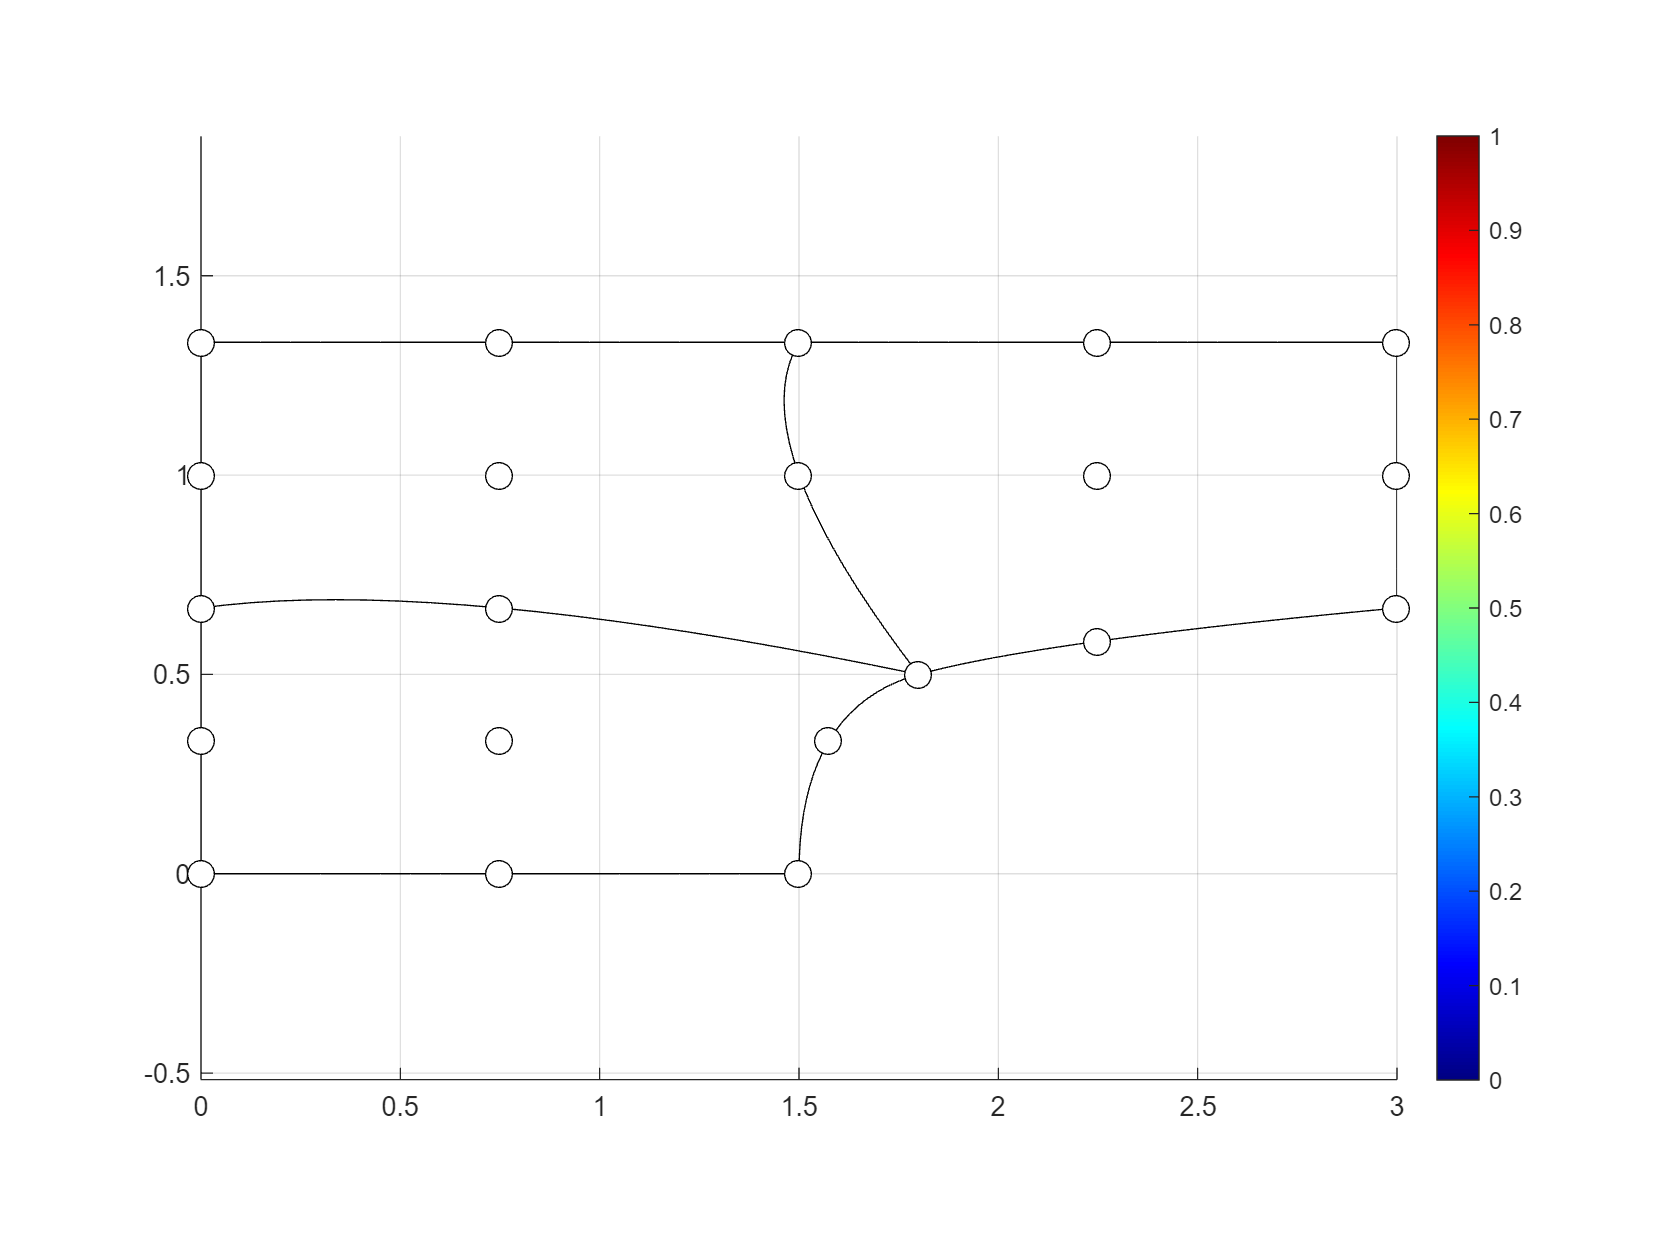

plotQuadraticElements(nodes, elements); grid on;

% Helper variables
nNodes = size(nodes, 1);
dofPerNode = 2;

nElements       = size(elements, 1);
nodesPerElement = size(elements, 2);
dofPerElement   = dofPerNode * nodesPerElement;
elementDOFs     = globalElementDOFs(shapefun_elements, 2);

## Generalized stiffness assembly

Set up system matrices

K = zeros(dofPerNode * nNodes);
u = zeros(dofPerNode * nNodes, 1);
f = zeros(dofPerNode * nNodes, 1);

% Set up stiffness matrix by looping over elements
integrationOrder = 3;
for e = 1 : nElements
    elementNodes = nodes(shapefun_elements(e, :), :);
    KE = elementStiffness(C, elementNodes, integrationOrder);
    
    % Use element connectivity to add element stiffness to global stiffness matrix
    K(elementDOFs(e, :), elementDOFs(e, :)) =   K(elementDOFs(e, :), elementDOFs(e, :)) + ...
                                                KE; 
end

% Load
f([22, 42]) = 77.78;
f(32) = 311.11;

% Solve system
fixeddofs = [1,2,4,6];
freedofs = setdiff(1 : nNodes * dofPerNode, fixeddofs);

u(freedofs) = K(freedofs, freedofs) \ f(freedofs);
u([41,42])

ans =    -0.0393
    0.0964


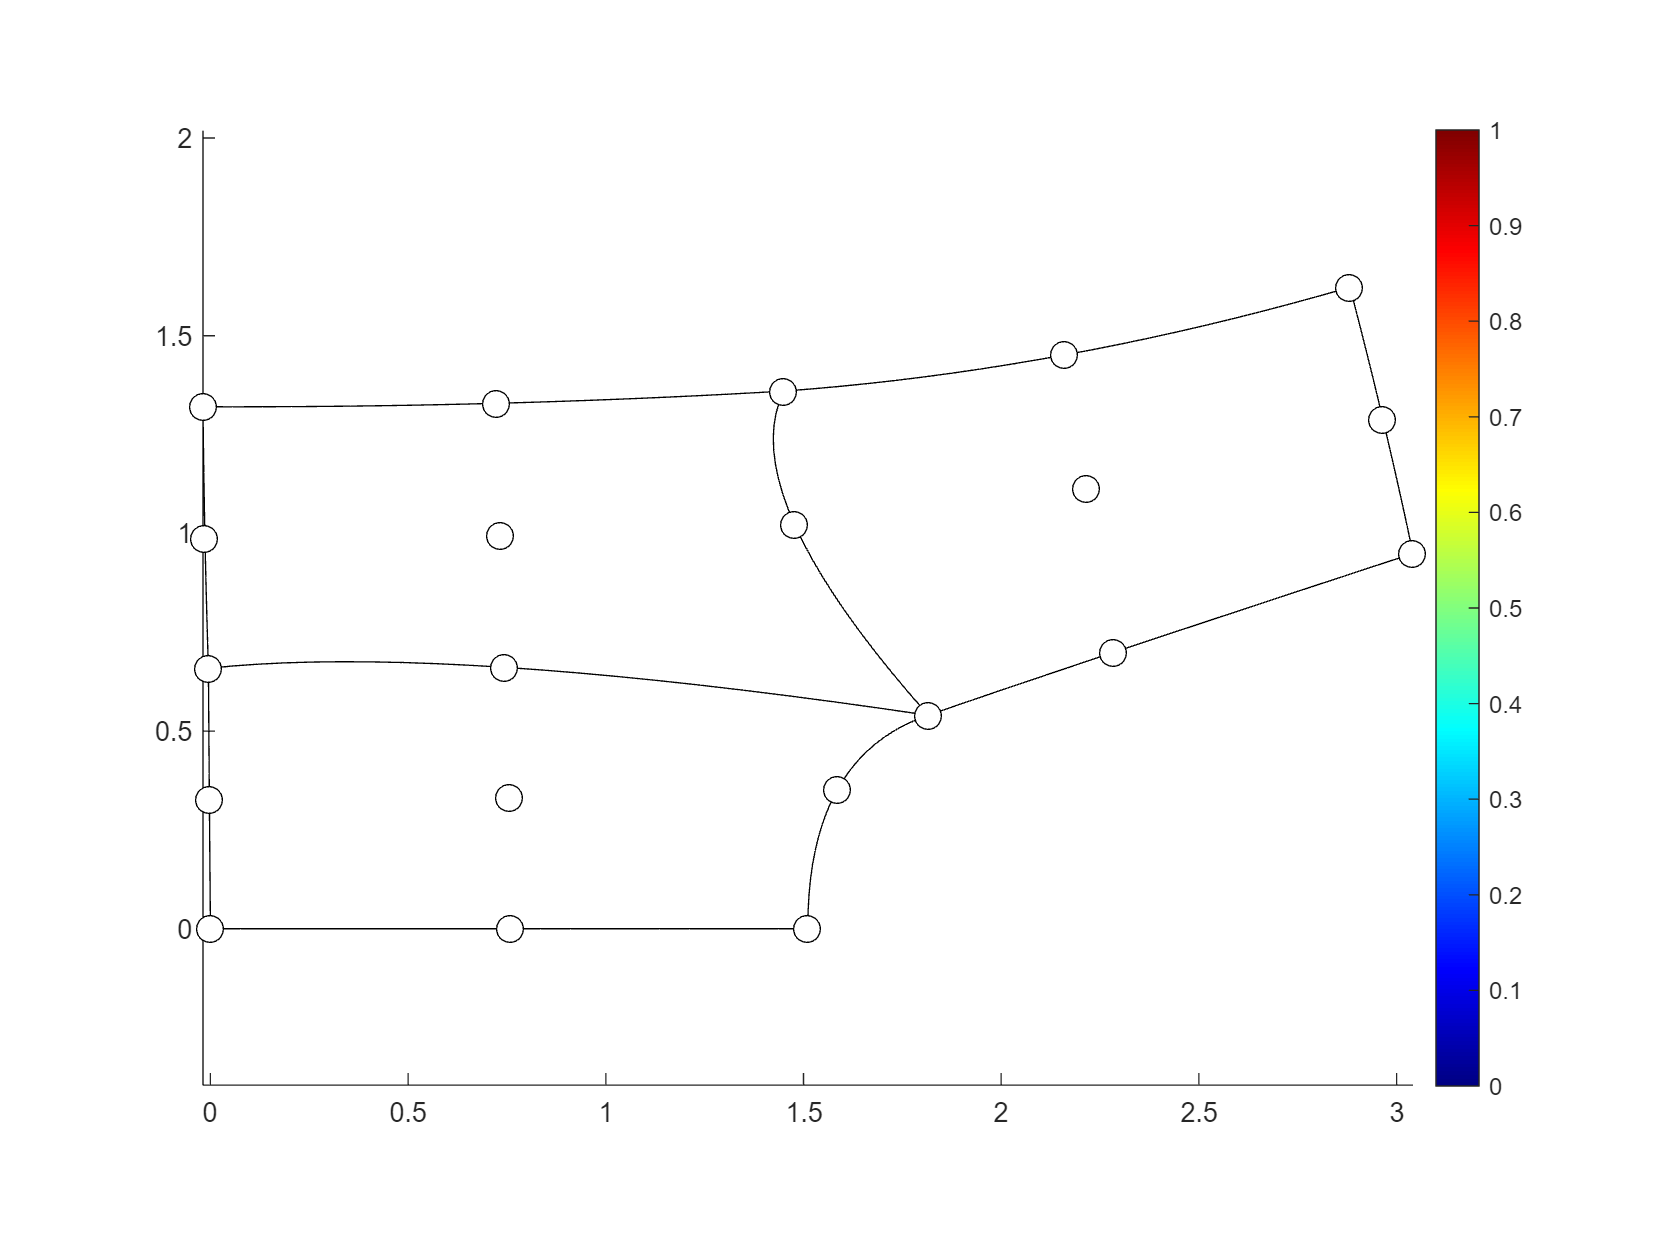

% Plot displacement as x0 + u
scale = 3;
uNodes = transpose(reshape(u, dofPerNode, nNodes));
uMagnitude = vecnorm(uNodes, 2, 2);
% plotElements(nodes + scale * uNodes, elements, '|u|', uMagnitude);
plotQuadraticElements(nodes + scale * uNodes, elements);

## Additional functions

function [xg, wg] = gaussianPoints2D(n)
    % Return integration points and weights for 2D gauss integration of order n
    % INPUT
    %   n (scalar)      OPTIONAL, order for integration, default: 2
    % OUTPUT
    %   xg (array)      Gaussian points in 2D
    %   wg (array)      Combined weights for 2D integration points

    if nargin < 1
        n = 2;
    end
    
    switch n
        case 1
            xg = [0, 0];
            wg = 2 * 2;
        case 2
            xg = [-1/sqrt(3), -1/sqrt(3);
                   1/sqrt(3), -1/sqrt(3);
                   1/sqrt(3),   1/sqrt(3);
                  -1/sqrt(3),  1/sqrt(3);];
            wg = ones(4,1);
        case 3
            % xg = [-sqrt(3/5), -sqrt(3/5);
            %       0, -sqrt(3/5);
            %       sqrt(3/5), -sqrt(3/5);
            %       -sqrt(3/5), 0;
            %       0, 0;
            %       sqrt(3/5), 0;
            %       -sqrt(3/5), sqrt(3/5);
            %       0, sqrt(3/5);
            %       sqrt(3/5), sqrt(3/5)];
            % wg = [5/9 * 5/9;
            %       8/9 * 5/9;
            %       5/9 * 5/9;
            %       5/9 * 8/9;
            %       8/9 * 8/9;
            %       5/9 * 8/9;
            %       5/9 * 5/9;
            %       8/9 * 5/9;
            %       5/9 * 5/9];

            xg = [  sqrt(3/5), sqrt(3/5);
                    -sqrt(3/5), sqrt(3/5);
                    -sqrt(3/5), -sqrt(3/5);
                    sqrt(3/5), -sqrt(3/5);
                    0, sqrt(3/5);
                    -sqrt(3/5), 0;
                    0, -sqrt(3/5);
                    sqrt(3/5), 0;
                    0, 0;
                ];
            wg = [  5/9 * 5/9;
                    5/9 * 5/9;
                    5/9 * 5/9;
                    5/9 * 5/9;
                    8/9 * 5/9;
                    5/9 * 8/9;
                    8/9 * 5/9;
                    5/9 * 8/9;
                    8/9 * 8/9;
                ];
        otherwise
            error('Integration points for order %d not implemented', n);
    end
end
function elementDOFs = globalElementDOFs(elements, dim)
    % Return global DOFs for elements
    % INPUT
    %   elements (array)    nodes per element as (nElements x nodesPerElement) array
    %   dim (scalar)        dimension
    % OUTPUT
    %   elementDOFs (array) global DOFs per element as (nElements x (dim * nodesPerElement)) array

    switch dim
        case 1
            elementDOFs = elements;
        case 2
            nodes = reshape(elements', numel(elements), 1);
            elementDOFs = [2 * nodes - 1, 2 * nodes]';
            elementDOFs = transpose(reshape(elementDOFs(:), 2 * size(elements, 2), size(elements, 1)));
        otherwise
            error("not implemented");
    end
end

function KE = elementStiffness(C, elementNodes, integrationOrder)
    % Compute element stiffness matrix
    % INPUT
    %   C (array)                   Constitutive matrix
    %   elementNodes (array)               Nodes for element
    %   integrationOrder (scalar)   Integration order for gauss quadrature
    % OUTPUT
    %   KE (array)                  Element stiffness matrix

    KE = zeros(size(elementNodes, 1) * size(elementNodes, 2));

    [xg, wg] = gaussianPoints2D(integrationOrder);                  % STEP1: GAUSS POINTS

    % Integrate stiffness
    for g = 1 : size(xg, 1)
        [~, dh] = quadraticShapeFunctions(xg(g, 1), ...           % STEP2: DERIVATIVES OF SHAPE FUNCTIONS w.r.t. r,s,t
                                          xg(g, 2));              
        J = dh * elementNodes;                                      % STEP3: JACOBIAN

        dhdx = J \ dh; % inv(J) * dh;
        B = bMatrix(dhdx, integrationOrder);                        % STEP4: DERIVATIVES OF SHAPE FUNCTIONS w.r.t. x,y,z -> B matrix

        KE = KE + wg(g) * B' * C * B * abs(det(J));                 % STEP5: STIFFNESS MATRIX
    end

end

% Shape functions
function [h, dh] = linearShapeFunctions(r, s)
    % Evaluate shape functions for linear quadrilateral element
    % INPUT
    %   r (array)   r coordinate for evaluation of shape functions and derivatives in natural coordinates
    %   s (array)   s coordinate for evaluation of shape functions and derivatives in natural coordinates
    % OUTPUT
    %   h (array)           Shape functions at (r, s), row per given point
    %   dh (array)          Derivatives of shape functions at first (r, s)

    h1 = 1/4 * (1 - r) .* (1 - s);
    h2 = 1/4 * (1 + r) .* (1 - s);
    h3 = 1/4 * (1 + r) .* (1 + s);
    h4 = 1/4 * (1 - r) .* (1 + s);

    dh1dr = -1/4 * (1 - s);
    dh1ds = -1/4 * (1 - r);
    dh2dr = 1/4 * (1 - s);
    dh2ds = -1/4 * (1 + r);
    dh3dr = 1/4 * (1 + s);
    dh3ds = 1/4 * (1 + r);
    dh4dr = -1/4 * (1 + s);
    dh4ds = 1/4 * (1 - r);

    h = [h1, h2, h3, h4];
    dh = [dh1dr, dh1ds;
          dh2dr, dh2ds;
          dh3dr, dh3ds;
          dh4dr, dh4ds]';
end

function [h, dh] = quadraticShapeFunctions(r, s)
    % Evaluate second order shape functions for quadrilateral element
    % INPUT
    %   r (array)   r coordinate for evaluation of shape functions and derivatives in natural coordinates
    %   s (array)   s coordinate for evaluation of shape functions and derivatives in natural coordinates
    % OUTPUT
    %   h (array)   Shape functions at (r, s), row per given point
    %   dh (array)  Derivatives of shape functions at first (r, s)
    
    h9 = (1 - r.^2)       .* (1 - s.^2);
    h8 = 1/2 * (1 + r)    .* (1 - s.^2) - h9 / 2;
    h7 = 1/2 * (1 - r.^2) .* (1 - s)    - h9 / 2;
    h6 = 1/2 * (1 - r)    .* (1 - s.^2) - h9 / 2; 
    h5 = 1/2 * (1 - r.^2) .* (1 + s)    - h9 / 2;
    h4 = 1/4 * (1 + r)    .* (1 - s)    - h7 / 2 - h8 / 2 - h9 / 4;
    h3 = 1/4 * (1 - r)    .* (1 - s)    - h6 / 2 - h7 / 2 - h9 / 4;
    h2 = 1/4 * (1 - r)    .* (1 + s)    - h5 / 2 - h6 / 2 - h9 / 4;
    h1 = 1/4 * (1 + r)    .* (1 + s)    - h5 / 2 - h8 / 2 - h9 / 4;

    dh9dr = -2 * r .* (1 - s.^2);
    dh9ds = -2 * s .* (1 - r.^2);

    dh8dr = 1/2 .* (1 - s.^2)           - dh9dr / 2;
    dh8ds = -s .* (1 + r)               - dh9ds / 2;

    dh7dr = -r .* (1 - s)               - dh9dr / 2;
    dh7ds = -1/2 .* (1 - r.^2)          - dh9ds / 2;

    dh6dr = -1/2 .* (1 - s.^2)          - dh9dr / 2;
    dh6ds = -s .* (1 - r)               - dh9ds / 2;

    dh5dr = -r .* (1 + s)               - dh9dr / 2;
    dh5ds = 1/2 .* (1 - r.^2)           - dh9ds / 2;

    dh4dr = 1/4 .* (1 - s)              - dh9dr / 4     -dh7dr/2 -dh8dr/2;
    dh4ds = -1/4 .* (1 + r)             - dh9ds / 4     -dh7ds/2 -dh8ds/2;

    dh3dr = -1/4 .* (1 - s)             - dh9dr / 4     -dh6dr/2 -dh7dr/2;
    dh3ds = -1/4 .* (1 - r)             - dh9ds / 4     -dh6ds/2 -dh7ds/2;
    
    dh2dr = -1/4 .* (1 + s)             - dh9dr / 4     -dh5dr/2 -dh6dr/2;
    dh2ds = 1/4 .* (1 - r)              - dh9ds / 4     -dh5ds/2 -dh6ds/2;
    
    dh1dr = 1/4 .* (1 + s)              - dh9dr / 4     -dh5dr/2 -dh8dr/2;
    dh1ds = 1/4 .* (1 + r)              - dh9ds / 4     -dh5ds/2 -dh8ds/2;

    % h = [h3, h7, h4, h6, h9, h8, h2, h5, h1];
    % dh = [dh3dr, dh3ds;
    %       dh7dr, dh7ds;
    %       dh4dr, dh4ds;
    %       dh6dr, dh6ds;
    %       dh9dr, dh9ds;
    %       dh8dr, dh8ds;
    %       dh2dr, dh2ds;
    %       dh5dr, dh5ds;
    %       dh1dr, dh1ds]';

    h = [h1, h2, h3, h4, h5, h6, h7, h8, h9];
    dh = [dh1dr, dh1ds;
          dh2dr, dh2ds;
          dh3dr, dh3ds;
          dh4dr, dh4ds;
          dh5dr, dh5ds;
          dh6dr, dh6ds;
          dh7dr, dh7ds;
          dh8dr, dh8ds;
          dh9dr, dh9ds]';
end

% H and B matrices
function H = hMatrix(r, s)
    % Evaluate H matrix for linear quadrilaterial element
    % INPUT
    %   r (array)   r coordinate for for evaluation of shape functions and derivatives in natural coordinates
    %   s (array)   s coordinate for for evaluation of shape functions and derivatives in natural coordinates
    % OUTPUT
    %   H (array)   B matrix for linear quadrilateral element in natural coordinates

    h = linearShapeFunctions(r, s);
    H = [h(1), 0, h(2), 0, h(3), 0, h(4), 0;
         0, h(1), 0, h(2), 0, h(3), 0, h(4)];
end

function B = bMatrix(dhdx, order)
    % Evaluate B matrix for quadrilaterial element
    % INPUT
    %   r (array)   r coordinate for for evaluation of shape functions and derivatives in natural coordinates
    %   s (array)   s coordinate for for evaluation of shape functions and derivatives in natural coordinates
    % OUTPUT
    %   B (array)   B matrix for linear quadrilateral element in natural coordinates

    % Initialize B matrix
    if order == 1
        nNodes = 4;
    else
        nNodes = 9;
    end
    B = zeros(3, 2 * nNodes);

    % Define linear indices for first B matrix -> B1 corresponding to node 1
    indicesBi = [1; 5; 3; 6];
    indicesdHi = [1; 2; 2; 1];

    % Repeat indices for node 2 to node X
    indicesB = indicesBi + (0 : 6 : 6 * nNodes - 6);
    indicesdH = indicesdHi + (0 : 2 : nNodes * 2 - 2);

    % Assign dh entries to B matrix
    B(indicesB) = dhdx(indicesdH);
end

% Plot functions
function p = plotElements(nodes, elements, title, color)
    % Plot elements by plotting a patch for each element
    % INPUT
    %   nodes (array)       Nodal coordinates as (nNodes x 2) array
    %   elements (array)    Nodal indices per element as (nElements x 4) array
    %   color (array)       OPTIONAL: Color for nodes or elements per row
    % OUTPUT
    %   p (array)           Patches for elements

    newFigure(title);
    hold on;
    for e = 1 : size(elements, 1)
        elementNodes = nodes(elements(e, :), :);
        % Reorder nodes for second order element for Matlab patch
        elementNodes = elementNodes([1 5 2 6 3 7 4 8], :);
        p(e) = patch(elementNodes(:, 1), elementNodes(:, 2), 'w');
        if nargin > 3
            if size(color, 1) == size(nodes, 1)
                % Interpolate between nodal values
                p(e).set('FaceColor', 'interp', 'FaceVertexCData', color(elements(e, :)));
            elseif size(color, 1) == size(elements, 1)
                % Color per element
                p(e).set('FaceColor', 'flat', 'FaceVertexCData', color(e));
            end
            clim([min(color), max(color)]);
            % p(e).EdgeAlpha = 0;
        else
            p(e).FaceAlpha = 0;
        end
    end
    hold off;
end

function plotQuadraticElements(nodes, elements)
    % Plot second-order elements by computing points on edge of element in (x, y)
    % INPUT
    %   nodes (array)       Nodal coordinates as (nNodes x 2) array
    %   elements (array)    Nodal indices per element as (nElements x 4) array

    newFigure();
    hold on;

    % Set up vectors for (r,s)-coordinates along edge of isoparametric element
    rs = [-1 : 0.1 : 1]';
    r = [rs; ones(numel(rs) - 2, 1); flip(rs); -1 * ones(numel(rs) - 2, 1); -1];
    s = [-1 * ones(numel(rs), 1); rs(2 : end - 1); ones(numel(rs), 1); flip(rs(2 : end - 1)); -1];
    
    % Loop over elements to plot contour for each element
    for e = 1 : size(elements, 1)
        elementNodes = nodes(elements(e, :), :);

        % Get shape functions for points along edge
        h = quadraticShapeFunctions(r, s);

        % Compute (x, y) data for (r, s) along edges 
        x = h * elementNodes(:, 1);
        y = h * elementNodes(:, 2);

        % Connect data points by plotting lines
        plot(x, y, 'k');

        % Optional: Plot nodes
        scatter(elementNodes(:, 1), elementNodes(:, 2), 'o', 'filled', ...
            'MarkerEdgeColor','k','MarkerFaceColor','w','SizeData', 100);
    end
    hold off;
end

function f = newFigure(figureTitle)
    % Open figure and set several common options
    % INPUT
    %   figureTitle (string/char array)     OPTIONAL: title for figure
    % OUTPUT
    %   f (figure) 

    f = figure;
    f.Position([3, 4]) = 1.5 * f.Position([3, 4]);
    f.Position(2) = f.Position(2) - f.Position(4)/3;
    axis equal; 
    colormap jet;
    colorbar;
    if nargin > 0
        title(figureTitle);
    end
end